Start

clear
channel_counts = 3;
unit = round(1/3, 2);
close all

test

/Volumes/MacProHD1/Dropbox/WUCCI_dropbox/Mast_lab/raw_test_resized/1979a-0002-TIFF-Export-01_s1.tif


TiffDelegateReader initializing /Volumes/MacProHD1/Dropbox/WUCCI_dropbox/Mast_lab/raw_test_resized/1979a-0002-TIFF-Export-01_s1.tif
Reading IFDs
Populating metadata
Checking comment style
Populating OME metadata
Reading series #1
    ...


stats =     Area         Centroid        BoundingBox               SubarrayIdx               MajorAxisLength    MinorAxisLength    Eccentricity    Orientation      ConvexHull         ConvexImage       ConvexArea          Image             FilledImage       FilledArea    EulerNumber      Extrema       EquivDiameter    Solidity    Extent       PixelIdxList         PixelList        Perimeter    PerimeterOld    Circularity    Aspectratio    Roundness
    _____    ________________    ____________    

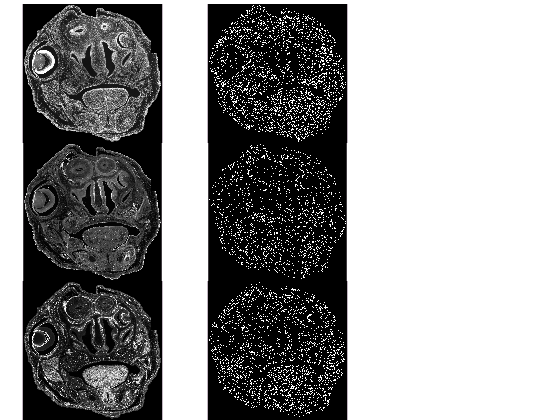

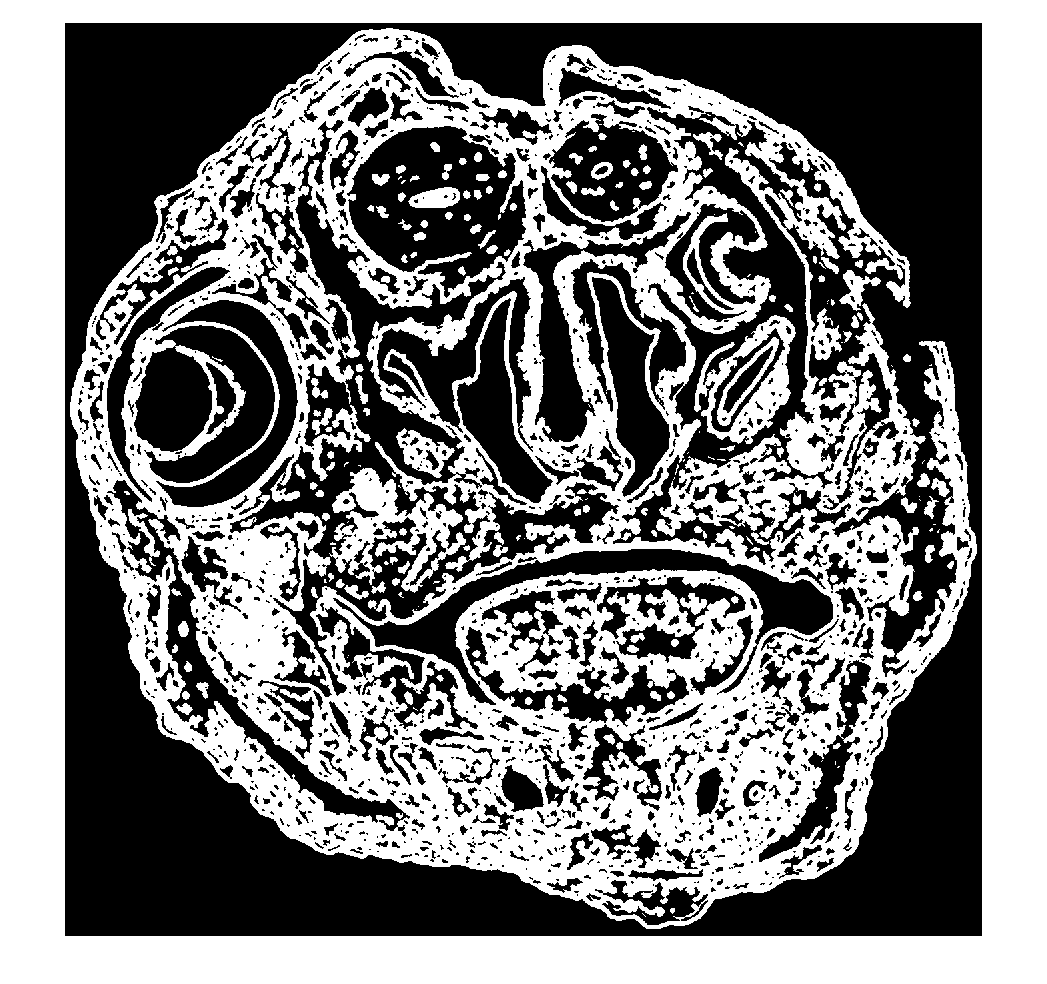

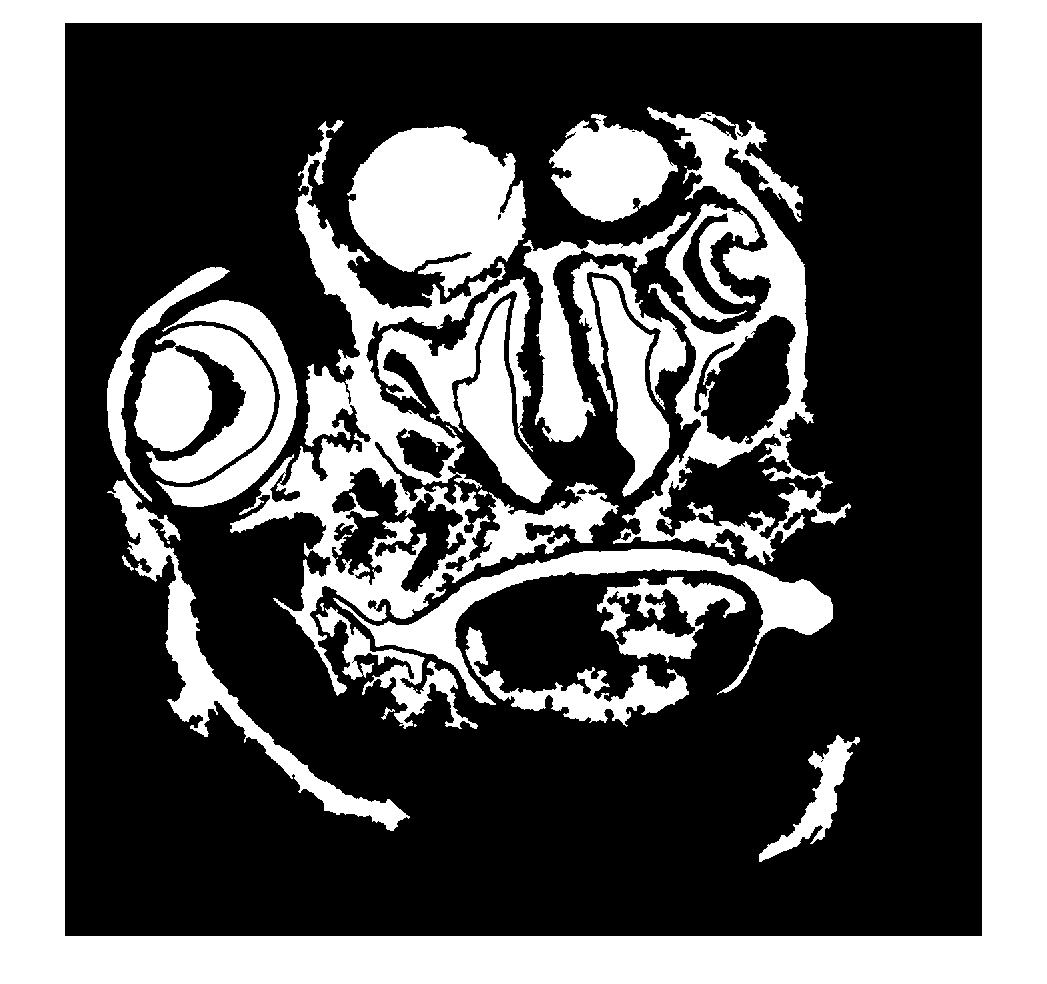

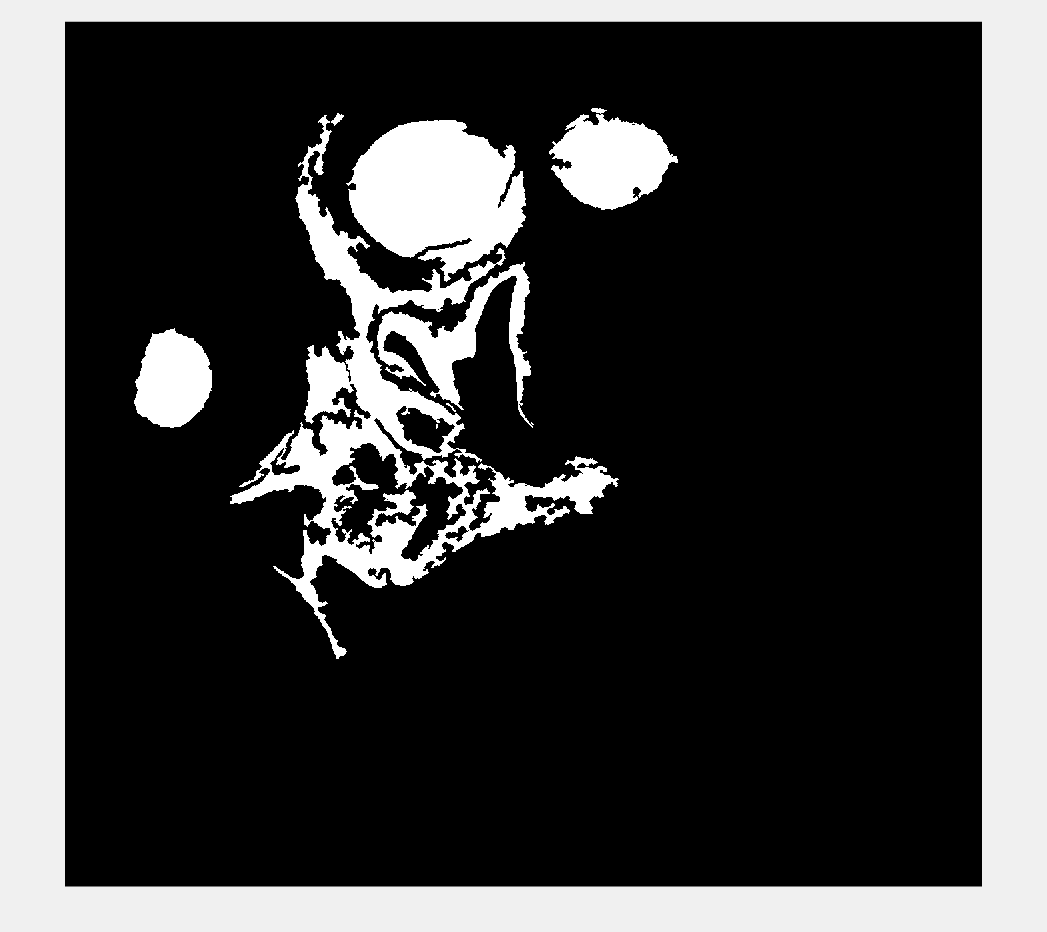

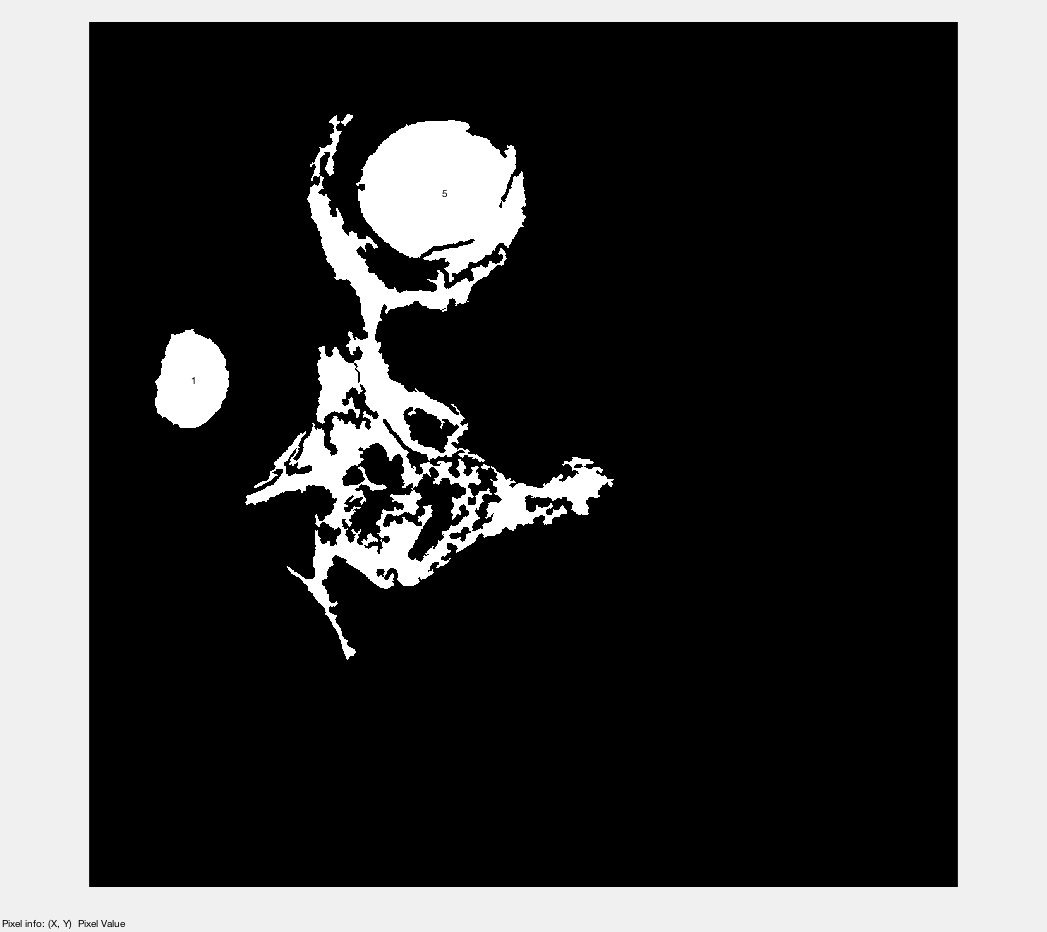

%% Define the path of folders
folder_path = '/Volumes/MacProHD1/Dropbox/WUCCI_dropbox/Mast_lab';
input_folder = 'raw_test_resized'; % specify the input folder
output_folder = 'raw_test_output'; % specify the output folder
input = dir(fullfile(folder_path, input_folder));
filenames = {input.name}'; % get filenames

%% Remove hidden files (any filenames start with ".").  
regexp_crit = '^[^.]+'; % the pattern of general expression
rxResult = regexp(filenames, regexp_crit); % pick the string follow the rule
nodot = (cellfun('isempty', rxResult)==0); % convert to logicals
filenames_nodot = filenames(nodot); % use logicals select filenames


%% run through image() function
for n = 1:1
    
    %n = 1:size(filenames_nodot, 1)
    %% load img through bio-format
    % create file list for each file
    img_file = fullfile(folder_path, input_folder, filenames_nodot(n));
    img_file = char(img_file); 
    disp(img_file);    
    
    data = bfopen(img_file);
    
    size = [10, 10];
    img_1 = double(data{1, 1}{1, 1});
    img_1 = padarray(img_1, size, 0, 'both');
    
    img_2 = double(data{1, 1}{2, 1});
    img_2 = padarray(img_2, size, 0, 'both');
    
    img_3 = double(data{1, 1}{3, 1});  
    img_3 = padarray(img_3, size, 0, 'both');
    
    %% plot image

    pos1 = [0 unit*2 unit unit];
    subplot('Position',pos1)
    imshow(img_1, []);

    pos3 = [0 unit unit unit];
    subplot('Position',pos3)
    imshow(img_2, []);

    pos5 = [0 0 unit unit];
    subplot('Position',pos5)
    imshow(img_3, []);

    %% findedge

    edgeim_1 = edge(img_1, 'canny', [0.07, 0.1], 2);
    pos2 = [unit unit*2 unit unit];
    subplot('Position',pos2);
    imshow(edgeim_1, [])

    edgeim_2 = edge(img_2, 'canny', [0.07, 0.1], 2);
    pos4 = [unit unit unit unit];
    subplot('Position',pos4);
    imshow(edgeim_2, [])

    edgeim_3 = edge(img_3, 'canny', [0.03, 0.1], 2);
    pos4 = [unit 0 unit unit];
    subplot('Position',pos4);
    imshow(edgeim_3, [])


    %% binary operation
    se = strel('disk',4,0);
    dilated_2 = imdilate(edgeim_2, se);
    dilated_3 = imdilate(edgeim_3, se);

    edge_merge = bitand(dilated_2, dilated_3);
    edge_merge = imerode(edge_merge, strel('disk', 1, 0));
    figure 
    imshow(edge_merge);

    % dilatedImage = imdilate(C, strel('disk',2 ));

    edge_cleaned = bwareaopen(edge_merge, 2000);
    % thinedImage = bwmorph(C,'thin',inf);

    edge_cleaned = imcomplement(edge_cleaned);
    figure 
    imshow(edge_cleaned);
    impixelinfo;


    %% keep biggest 20 area

    big_area = bwareafilt(edge_cleaned, 21,'largest');
    big_area = bwareafilt(big_area, 20,'smallest');


    %% BW statistic s
    stats = regionprops('table', big_area, 'all');
    stats.Circularity = (4*pi*stats.Area)./((stats.Perimeter).^2);
    stats.Aspectratio = stats.MajorAxisLength./stats.MinorAxisLength; 
    stats.Roundness = (4*stats.Area)./(pi*(stats.MajorAxisLength).^2); 
    stats
    
    figure 
    imshow(big_area);
%     hold on
%     scatter(centroids(:, 1), centroids(:, 2)) ;
%     hold off
    
    stats = sortrows(stats, 'Eccentricity');
    BW2 = bwpropfilt(big_area, 'Eccentricity', 5, 'smallest'); 
    stats_2 = stats(1:5, :);
    imshow(BW2);
    
    
    cc = bwconncomp(BW2); 
    idx = find([stats_2.Circularity] > 0.2);
    BW3 = ismember(labelmatrix(cc), idx);

    stats_2 = stats(stats.Circularity > 0.2, :);
    stats_2 = sortrows(stats_2, 'Circularity', 'descend');
    
    centroids = stats_2.Centroid; 
    
    figure 
    imshow(BW3);
    hold on
    
    for k= 1: height(stats_2);
        text(centroids(k, 1), centroids(k, 2), num2str(k));
    end
    
    hold off
    
    impixelinfo;
    
    
    
end